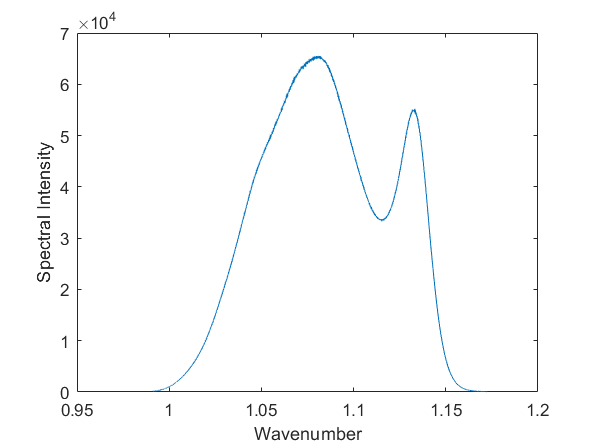

clear; clc;
format short g
%Original spectral interference signal
handle  = OCTFileOpen('Default_0193_Mode2D.oct');
NrRawData = OCTFileGetNrRawData(handle);
[RawData, Spectrum] = OCTFileGetRawData(handle, 0);
load('Wavelength.mat','Wavelength');
intensity = zeros(1,length(Spectrum));
wavelength = zeros(1,length(Wavelength));
for i = 1:length(Wavelength)
    wavelength(length(wavelength)+1-i) = Wavelength(i);
    intensity(length(intensity)+1-i) = Spectrum(i);
end
%波长映射到波数
sigma = 1./wavelength;
%波数均匀采样
sigma_inter = linspace(sigma(1),sigma(end),4*length(sigma)); 
%光谱强度三次样条插值
intensity_inter = spline(sigma,intensity,sigma_inter);
figure(4);plot(sigma_inter,intensity_inter);
xlabel('Wavenumber');ylabel('Spectral Intensity');

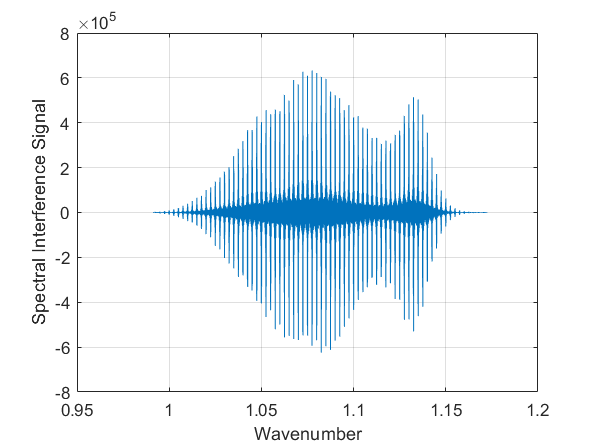

%光谱干涉信号S(\sigma) = A(\sigma)*cos(4\pi*(z-z0)*\sigma-4\pi*T*n(\sigma)*\sigma)
spec_signal = intensity_inter;

%设置参数：
z1 = [300 500 700 900 1100 1300 1500 1700 1900 2100];
z0 = 0;
T = 1500;
%加入色散
%色散公式
lambda = 1./sigma_inter;
index2 = (1.03961212*lambda.^2)./(lambda.^2-0.00600069867)+(1.01046945*lambda.^2)./...
        (lambda.^2-103.560653)+(0.231792344*lambda.^2)./(lambda.^2-0.0200179144)+1; 
index = sqrt(abs(index2));
%%存在问题
signalSum = zeros(1,length(sigma_inter));
%加入样品色散
for i = 1:length(z1)
interference_signal = spec_signal.*cos(4*pi*(z1(i)-z0).*sigma_inter+4*pi.*index*T.*...
    sigma_inter);%+2*spec_signal;
signalSum = interference_signal + signalSum;
end
interference_signal = signalSum;
figure(5);plot(sigma_inter,interference_signal);
xlabel('Wavenumber');ylabel('Spectral Interference Signal');

%对光谱进行傅里叶变换
Nfft = 2^20;
fft_signal = fft(interference_signal,Nfft);
interference_signal = fftshift(fft_signal);
deltaSigma = (sigma_inter(end)-sigma_inter(1))/(length(sigma_inter)-1);
deltaZ = 1/(2*Nfft*deltaSigma);
z = (1:Nfft)*deltaZ;
intensity_fft = abs(interference_signal);
% angle_fft = angle(interference_signal);
%坐标变换
z = z-z(end)/2;
% figure(6);
% intensity_fft = intensity_fft(length(intensity_fft)/2+1:end);
% z = z(length(z)/2+1:end);
grid

threshold = max(intensity_fft)/1.2;
findpeaks(intensity_fft,z,'MinPeakHeight',threshold,'Annotate','extents')
[pks,locs,w,p] = findpeaks(intensity_fft,z,'MinPeakHeight',threshold,...
                'Annotate','extents')

pks =     1.2605    1.2605    1.2606    1.2606    1.2606    1.2606    1.2606    1.2606    1.2605    1.2604    1.2604    1.2605    1.2606    1.2606    1.2606    1.2606    1.2606    1.2606    1.2605    1.2605


locs =    -4.3845   -4.1845   -3.9845   -3.7845   -3.5845   -3.3845   -3.1845   -2.9845   -2.7845   -2.5845    2.5845    2.7845    2.9845    3.1845    3.3845    3.5845    3.7845    3.9845    4.1845    4.3845


w =     5.5042    5.5041    5.5045    5.5044    5.5043    5.5044    5.5044    5.5043    5.5043    5.5044    5.5044    5.5043    5.5043    5.5044    5.5044    5.5043    5.5044    5.5045    5.5041    5.5042


p =     1.2605    1.2605    1.2606    1.2606    1.2606    1.2605    1.2605    1.2606    1.2605    1.2604    1.2604    1.2605    1.2606    1.2605    1.2605    1.2606    1.2606    1.2606    1.2605    1.2605


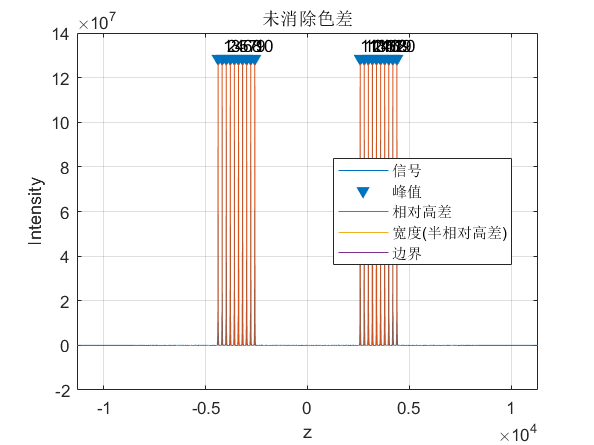

text(locs,pks+pks/15,num2str((1:numel(pks))'));
xlabel('z');ylabel('Intensity');title("未消除色差");

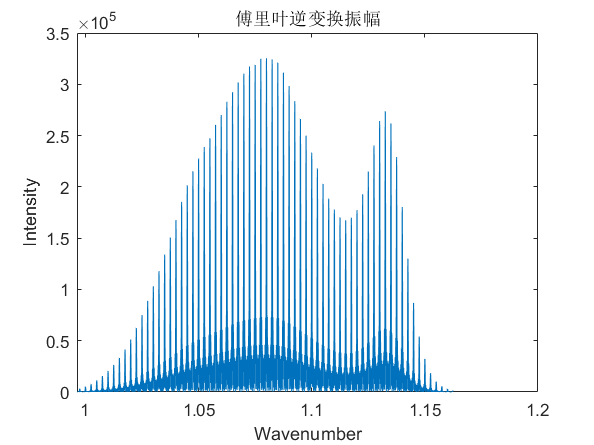

% figure(7);plot(z,unwrap(angle_fft));

%傅里叶逆变换

ifft_signal = fft_signal(1:length(fft_signal)/2);
% Nfft = 2^20;
ifft_signal = ifft(ifft_signal,Nfft);
interference_signal = ifftshift(ifft_signal);
deltaz = (z(end)-z(1))/(length(z)-1);
deltasigma = 1/(2*Nfft*deltaz);
sigma = (1:Nfft)*deltasigma;
intensity_ifft = abs(interference_signal);
angle_ifft = angle(interference_signal);
%坐标变换
sigma = sigma-sigma(end)/2+sigma_inter(1);
[~, indix_min] = min(abs(sigma-sigma_inter(1)-0.005));%sigma_inter(1)
[~, indix_max] = min(abs(sigma-sigma_inter(end)+0.01));%sigma_inter(end)
figure(6);plot(sigma(indix_min:indix_max),intensity_ifft(indix_min:indix_max));
xlabel('Wavenumber');ylabel('Intensity');title("傅里叶逆变换振幅")

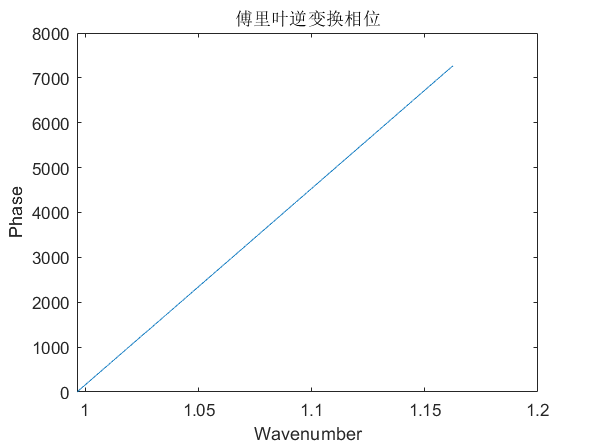

sigma = sigma(indix_min:indix_max);angle_fit = unwrap1(unwrap(...
        angle_ifft(indix_min:indix_max)));
[pha_idx, v] = check_phase(angle_fit,deltasigma);

for n = 1:numel(pha_idx)
angle_fit(pha_idx(n)+1:end) = angle_fit(pha_idx(n)+1:end)+v;
end
% %%%存在问题
figure(7);plot(sigma,angle_fit);
xlabel('Wavenumber');ylabel('Phase');title("傅里叶逆变换相位")

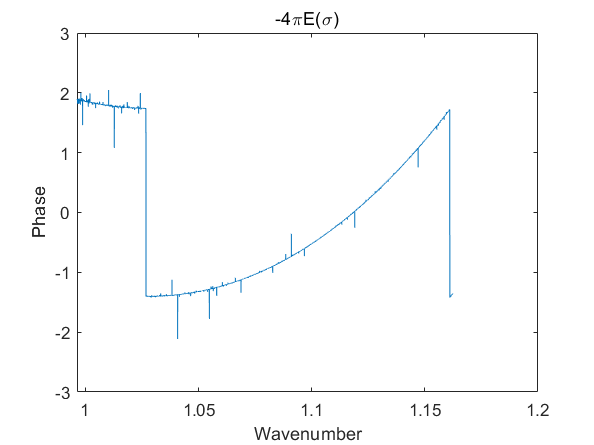

%数据拟合,得到4*pi*E = ang_fit-angle_fit
poly = polyfit(sigma,angle_fit,1);
ang_fit = polyval(poly,sigma);
nolinear_phase = angle_fit-ang_fit;
plot(sigma,nolinear_phase);
xlabel('Wavenumber');ylabel('Phase');title("-4\piE(\sigma)");

%----------------------------------------------------------------------------------------
% 求系数C
N = 2.5*10^3;
AMV = zeros(1,N);
AF = zeros(1,N);
SF = zeros(1,N);
% for i = 1:N
%  C= i*10^-6;
C = 1.5*10^-3%705*10^-6;

C =        0.0015


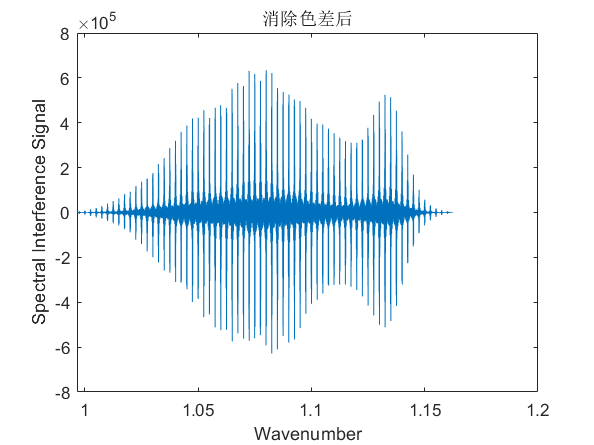

interference_signal1 = signalSum;
%将sigma用sigma+C*E(sigma)替代
sigma_inter1 = sigma+C*(angle_fit-ang_fit)/(4*pi);
%插值求得处理后的干涉信号,需要修正，首尾坐标选取sigma_inter、sigma_inter1中合适的值
sigma_find = (sigma_inter1>=sigma_inter(1) & sigma_inter1 <=sigma_inter(end));
sigma_inter1 = sigma_inter1(sigma_find);
signal_C = interp1(sigma_inter,interference_signal1,sigma_inter1,'spline');
plot(sigma_inter1,signal_C)
xlabel('Wavenumber');ylabel('Spectral Interference Signal');title("消除色差后");


%对光谱进行傅里叶变换
Nfft = 2^20;
fft_signal = fft(signal_C,Nfft);
interference_signal = fftshift(fft_signal);
deltaSigma = (sigma_inter1(end)-sigma_inter1(1))/(length(sigma_inter1)-1);
deltaZ = 1/(2*Nfft*deltaSigma);
z = (1:Nfft)*deltaZ;
intensity_fft = abs(interference_signal);
angle_fft = angle(interference_signal);

%坐标变换
z = z-z(end)/2;
z = z(length(z)/2+1:end);
intensity_fft = intensity_fft(length(intensity_fft)/2+1:end);
% plot(z,intensity_fft);
threshold = max(intensity_fft)/6;
findpeaks(intensity_fft,z,'MinPeakProminence',threshold,'MinPeakDistance',50,...
'Annotate','extents');
[pks,locs,w,p] = findpeaks(intensity_fft,z,'MinPeakProminence',threshold,...
                'MinPeakDistance',50,'Annotate','extents')

pks =     8.2411    8.1375    7.9981    7.6260    7.2926    7.5389    7.4437    7.1476    6.9495    7.0977


locs =     2.5974    2.7987    2.9995    3.2001    3.3967    3.5973    3.7979    3.9988    4.2001    4.4013


w =    13.1781   13.8327   14.3694   14.5891   14.7614   14.9443   15.9513   17.1402   17.8074   17.1956


p =     8.2410    8.1366    7.9934    7.6241    7.2665    7.5204    7.4416    7.1456    6.9435    7.0925


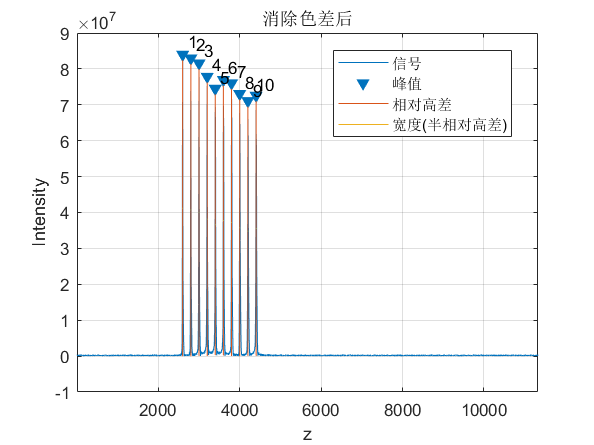

text(locs,pks+pks/15,num2str((1:numel(pks))'));
xlabel('z');ylabel('Intensity');title("消除色差后");

wdt = fwhm(intensity_fft,z,pks,locs,max(intensity_fft)/15)

wdt =    13.1782   13.8335   14.3734   14.5906   14.7830   14.9622   15.9540   17.1433   17.8204   17.2062


% %计算最大值的平均值 (AMV)
% AMV(i) = mean(pks);
% %计算FWHMs 的平均值
% AF(i) = mean(wdt);
% %计算FWHMs的标准差
% SF(i) = std(wdt);
% % end
% plot((10^-6)*(1:N),AMV);xlim([0 1.3]);
% plot((10^-6)*(1:N),AF);xlim([0 1.3]);
% plot((10^-6)*(1:N),SF);xlim([0 1.3]);



function p = unwrap1(p)
x = p(1);
for n = 2:length(p)
    diff = p(n)-x;
    if diff < 0
        x = p(n);
       p(n) = p(n-1)+diff+pi;
    elseif diff > 0
        x = p(n); 
        p(n) = p(n-1)+diff;
    end
end
end

%简单计算FWHM,threshold是划分区域的阈值
function wdt = fwhm(data,x,pks,locs,threshold)
%平滑处理
% data = smoothdata(data,'sgolay',4); 
% plot(x,data);
idx = diff(sign(data -threshold));
xlocs = x(find(idx));
wdt = zeros(1,numel(locs));
xfwhm = zeros(1,2);
% plot(wdt,data(idx),'*r')
for i = 1:length(locs)
    idx = find(diff(sign(xlocs-locs(i))));
    idx1 = find(~(x-xlocs(idx)));
    idx2 = find(~(x-xlocs(idx+1)));
    data1 = data(idx1:idx2);
    x1 = x(idx1:idx2);
    idx = find(diff(sign(data1-pks(i)/2)));
    for n = 1:numel(idx)
        idxrng = idx(n)-2:idx(n)+2;
        xfwhm(1,n) = interp1(data1(idxrng), x1(idxrng), pks(i)/2, 'pchip');
    end
    wdt(i) = xfwhm(end)-xfwhm(1);
end
end
function [pha,v] = check_phase(p,h)
q = zeros(1,length(p));
for i = 1:length(p)-1
    q(i) = (p(i+1)-p(i))/h;
end
q(end) = q(end-1);
a=find(abs(q-mean(q))>0.3*mean(q));
% d = find(diff(a) == 1)
ind = abs(q(a)+q(a+1)-2*mean(q))>mean(q);
pha = a(find(ind));
if q(pha)>mean(q);
    v = -pi; 
else
    v = pi;
end
end
